## **HCP Main Sample - External Validation 'Basic NMA Model' in AOMIC PIOP2 Sample **

Conduction of the external validation of the 'Basic NMA Model' that is built using two input predictor variables. The predictor variables are derived from individual's coupling value and extracted by using group-based positive and negative NMA masks. The script contains three parts: **Part 1 **partitions the sample into five different folds (considering intelligence distribution) and creates a positive and negative NMAs for each training fold (4/5 partition) and test fold (in this case the AOMIC PIOP2 sample). **Part 2 **uses the NMAs created in part 1 to build multiple linear regression models that are then tested for their ability to predict general intelligence in the test samples (AOMIC PIOP2 sample in this case). **Part 3 **assesses the significance of the prediction model with a permutation test. 

Before running this script:

- run all scripts in HCP Data Prep & AOMIC Data Prep

**Part 1**

Partitioning the sample into 5 different folds and creating the positive and negative NMAs for each training fold and test fold (in this case the AOMIC PIOP2 sample) based on the correlation with general intelligence scores.

**1. Prepare the coupling data for the HCP main sample **

1.1. Create a cell that contains for each subject a vector of 8 predictors for each node 

for i = 1:532
    x = final_r_all_HCP_rest_532{i,1};
    for j = 1:358
    Node_all_baseline_HCP{i,j} = x(j,:);
    end
end

1.2. Create cell that contains information from all subjects and all coupling measures for all nodes separetely (532*8)

% extract for each collumn 8 rows from each row and put them together in a matrix (--> I need 532*8 matrix for each node)

n = size(Node_all_baseline_HCP,2);
All_Nodes_complete_HCP = cell(1,n);
for j = 1:n
    All_Nodes_complete_HCP{j} = vertcat(Node_all_baseline_HCP{:,j});
end 

1.3. Only keep 4 measures: Path Length (1), Communicability (2), Cosine Distance (3), & Search Information (3)

for i = 1:358
    eight_measures_per_node = All_Nodes_complete_HCP{1,i};
    four_measures_per_node = eight_measures_per_node(:,1:4);
    All_Nodes_complete_HCP_4_measures{1,i} = four_measures_per_node;
end

**2. Prepare the coupling data for the replication sample (AOMIC PIOP2)**

2.1. Create a cell that contains for each subject a vector of 8 predictors for each node 

for i = 1:180
    x = final_r_all_AOMIC_PIOP2_rest_180{i,2};
    for j = 1:358
    Node_all_baseline_AOMIC_PIOP2{i,j} = x(j,:);
    end
end

2.2. Create a cell that contains information from all subjects and all coupling measures for all nodes separately (180 * 4) 

% extract for each collumn 4 rows from each row and put them together in a matrix (--> I need 180*4 Matrix for each node)

n = size(Node_all_baseline_AOMIC_PIOP2,2);
All_Nodes_complete_AOMIC_PIOP2 = cell(1,n);
for j = 1:n
    All_Nodes_complete_AOMIC_PIOP2{j} = vertcat(Node_all_baseline_AOMIC_PIOP2{:,j});
end 

**3. Split into 5 folds **

3.1. Create a loop to do the partition 100 times 

for cross_validation_round = 1:100
    display(cross_validation_round)

cross_validation_round = 1

cross_validation_round = 2

cross_validation_round = 3

cross_validation_round = 4

cross_validation_round = 5

cross_validation_round = 6

cross_validation_round = 7

cross_validation_round = 8

cross_validation_round = 9

cross_validation_round = 10

cross_validation_round = 11

cross_validation_round = 12

cross_validation_round = 13

cross_validation_round = 14

cross_validation_round = 15

cross_validation_round = 16

cross_validation_round = 17

cross_validation_round = 18

cross_validation_round = 19

cross_validation_round = 20

cross_validation_round = 21

cross_validation_round = 22

cross_validation_round = 23

cross_validation_round = 24

cross_validation_round = 25

cross_validation_round = 26

cross_validation_round = 27

cross_validation_round = 28

cross_validation_round = 29

cross_validation_round = 30

cross_validation_round = 31

cross_validation_round = 32

cross_validation_round = 33

cross_validation_round = 34

cross_validation_round = 35

cross_validation_round = 36

cross_validation_round = 37

cross_validation_round = 38

cross_validation_round = 39

cross_validation_round = 40

cross_validation_round = 41

cross_validation_round = 42

cross_validation_round = 43

cross_validation_round = 44

cross_validation_round = 45

cross_validation_round = 46

cross_validation_round = 47

cross_validation_round = 48

cross_validation_round = 49

cross_validation_round = 50

cross_validation_round = 51

cross_validation_round = 52

cross_validation_round = 53

cross_validation_round = 54

cross_validation_round = 55

cross_validation_round = 56

cross_validation_round = 57

cross_validation_round = 58

cross_validation_round = 59

cross_validation_round = 60

cross_validation_round = 61

cross_validation_round = 62

cross_validation_round = 63

cross_validation_round = 64

cross_validation_round = 65

cross_validation_round = 66

cross_validation_round = 67

cross_validation_round = 68

cross_validation_round = 69

cross_validation_round = 70

cross_validation_round = 71

cross_validation_round = 72

cross_validation_round = 73

cross_validation_round = 74

cross_validation_round = 75

cross_validation_round = 76

cross_validation_round = 77

cross_validation_round = 78

cross_validation_round = 79

cross_validation_round = 80

cross_validation_round = 81

cross_validation_round = 82

cross_validation_round = 83

cross_validation_round = 84

cross_validation_round = 85

cross_validation_round = 86

cross_validation_round = 87

cross_validation_round = 88

cross_validation_round = 89

cross_validation_round = 90

cross_validation_round = 91

cross_validation_round = 92

cross_validation_round = 93

cross_validation_round = 94

cross_validation_round = 95

cross_validation_round = 96

cross_validation_round = 97

cross_validation_round = 98

cross_validation_round = 99

cross_validation_round = 100

3.2. Create cross-validation partition based on family IQ

This part of the script creates a partition for the internal cross validation of the linear regression model that is stratified based on Family IQ. That way, we respect the family structures in the HCP and create a distribution of subjects in the test and training samples that is not biased towards general intelligence scores. 

3.2.1. Assign the variables

HCP_family_ID = HCP_behavioral_532.Family_ID;
HCP_subject_names = HCP_behavioral_532.("Subject Name");
HCP_intelligence_score = HCP_behavioral_532.gscore;

3.2.2. Create a table containing all the information that I need 

[number_of_families,~,family_group_number] = unique(HCP_behavioral_532.Family_ID); 
% there are 268 families in the main main sample (unique output 1)

for i = 1:268 % because there is 268 families in the sample (unique output 1) 
    
    indices_for_same_family = find(family_group_number == i);
    subject_ID_same_fam = HCP_subject_names(indices_for_same_family);
    family_ID_original = HCP_family_ID(indices_for_same_family);
    intelligence_score_same_fam = HCP_intelligence_score(indices_for_same_family);
    
    family_info_HCP{i,1} = i;
    family_info_HCP{i,2} = family_ID_original;
    family_info_HCP{i,3} = indices_for_same_family;
    family_info_HCP{i,4} = subject_ID_same_fam;
    family_info_HCP{i,5} = intelligence_score_same_fam;
    
end

3.2.3. Create a family intelligence score

for i = 1:268
    family_intelligence_separate = family_info_HCP{i,5};
    family_intelligence_average = mean(family_intelligence_separate);
    family_info_HCP{i,6} = family_intelligence_average;
end

3.2.4. Convert cell to table

family_info_HCP_table = cell2table(family_info_HCP);
family_info_HCP_table.Properties.VariableNames = {'Group Number','Original_Family_ID', 'Indices_for_same_Family', 'Subject_ID_same_fam', 'intelligence_score_separate_same_fam', 'Mean_intelligence_score_same_fam'};

3.2.5. Create a CV partition based on family IQ (for the families) 

Family_intelligence = family_info_HCP_table.Mean_intelligence_score_same_fam;


Intelligence_for_cv_partition_1 = rescale(Family_intelligence,1,30);
Intelligence_for_cv_partition = int16(Intelligence_for_cv_partition_1); % create 30 groups to ultimatly create a stratified cv partition


c = cvpartition(Intelligence_for_cv_partition,'KFold',5);

3.2.6. Create output: indices for the families

% Train 1 & Test 1 

index_test_1 = find(test(c,1));
index_train_1 = find(training(c,1));

% Train 2 & Test 2 
index_test_2 = find(test(c,2));
index_train_2 = find(training(c,2));

% Train 3 & Test 3 

index_test_3 = find(test(c,3));
index_train_3 = find(training(c,3));

% Train 4 & Test 4 

index_test_4 = find(test(c,4));
index_train_4 = find(training(c,4));

% Train 5 & Test 5 

index_test_5 = find(test(c,5));
index_train_5 = find(training(c,5));


3.2.7. Reassign the individual subjects back into the groups from the partition 

% Train 1 & Test 1 

test_1 = family_info_HCP_table.Indices_for_same_Family(index_test_1);
index_test_1_fam = cat(1,test_1{:,1});
index_test_1_fam = sort(index_test_1_fam,"ascend");

train_1 = family_info_HCP_table.Indices_for_same_Family(index_train_1);
index_train_1_fam = cat(1,train_1{:,1});
index_train_1_fam = sort(index_train_1_fam,"ascend");

% Train 2 & Test 2 

test_2 = family_info_HCP_table.Indices_for_same_Family(index_test_2);
index_test_2_fam = cat(1,test_2{:,1});
index_test_2_fam = sort(index_test_2_fam,"ascend");

train_2 = family_info_HCP_table.Indices_for_same_Family(index_train_2);
index_train_2_fam = cat(1,train_2{:,1});
index_train_2_fam = sort(index_train_2_fam,"ascend");


% Train 3 & Test 3 

test_3 = family_info_HCP_table.Indices_for_same_Family(index_test_3);
index_test_3_fam = cat(1,test_3{:,1});
index_test_3_fam = sort(index_test_3_fam,"ascend");

train_3 = family_info_HCP_table.Indices_for_same_Family(index_train_3);
index_train_3_fam = cat(1,train_3{:,1});
index_train_3_fam = sort(index_train_3_fam,"ascend");


% Train 4 & Test 4 

test_4 = family_info_HCP_table.Indices_for_same_Family(index_test_4);
index_test_4_fam = cat(1,test_4{:,1});
index_test_4_fam = sort(index_test_4_fam,"ascend");

train_4 = family_info_HCP_table.Indices_for_same_Family(index_train_4);
index_train_4_fam = cat(1,train_4{:,1});
index_train_4_fam = sort(index_train_4_fam,"ascend");


% Train 5 & Test 5 

test_5 = family_info_HCP_table.Indices_for_same_Family(index_test_5);
index_test_5_fam = cat(1,test_5{:,1});
index_test_5_fam = sort(index_test_5_fam,"ascend");

train_5 = family_info_HCP_table.Indices_for_same_Family(index_train_5);
index_train_5_fam = cat(1,train_5{:,1});
index_train_5_fam = sort(index_train_5_fam,"ascend");

% done with creating the training/test partition

3.3. Divide data in test and training samples 

3.3.1. Divide the coupling data into 5 training samples (test sets are not necessary) 

for i = 1:358
   all_data_node = All_Nodes_complete_HCP_4_measures{1,i};
   
   Node_training_sample_1 = all_data_node(index_train_1_fam,:);
   Node_test_sample_1 = all_data_node(index_test_1_fam,:);
   
   Node_training_sample_2 = all_data_node(index_train_2_fam,:);
   Node_test_sample_2 = all_data_node(index_test_2_fam,:);
   
   Node_training_sample_3 = all_data_node(index_train_3_fam,:);
   Node_test_sample_3 = all_data_node(index_test_3_fam, :);
   
   Node_training_sample_4 = all_data_node(index_train_4_fam,:);
   Node_test_sample_4 = all_data_node(index_test_4_fam,:);
   
   Node_training_sample_5 = all_data_node(index_train_5_fam,:);
   Node_test_sample_5 = all_data_node(index_test_5_fam, :);
   
   All_Nodes_complete_cross_validation_HCP_{1,i} = Node_training_sample_1;
   All_Nodes_complete_cross_validation_HCP_{2,i} = Node_training_sample_2;
   All_Nodes_complete_cross_validation_HCP_{3,i} = Node_training_sample_3;
   All_Nodes_complete_cross_validation_HCP_{4,i} = Node_training_sample_4;
   All_Nodes_complete_cross_validation_HCP_{5,i} = Node_training_sample_5;
   All_Nodes_complete_cross_validation_HCP_{6,i} = Node_test_sample_1;
   All_Nodes_complete_cross_validation_HCP_{7,i} = Node_test_sample_2;
   All_Nodes_complete_cross_validation_HCP_{8,i} = Node_test_sample_3;
   All_Nodes_complete_cross_validation_HCP_{9,i} = Node_test_sample_4;
   All_Nodes_complete_cross_validation_HCP_{10,i} = Node_test_sample_5;
   
end

3.3.2. Divide intelligence into 5 training samples

Intelligence = HCP_behavioral_532.gscore;
Intelligence_replication = AOMIC_PIOP2_behavioral_180.raven_score;

Intelligence_train_1 = Intelligence(index_train_1_fam,:);
Intelligence_train_2 = Intelligence(index_train_2_fam,:);
Intelligence_train_3 = Intelligence(index_train_3_fam,:);
Intelligence_train_4 = Intelligence(index_train_4_fam,:);
Intelligence_train_5 = Intelligence(index_train_5_fam,:);

Intelligence_training_samples{1,:} = Intelligence_train_1;
Intelligence_training_samples{2,:} = Intelligence_train_2;
Intelligence_training_samples{3,:} = Intelligence_train_3;
Intelligence_training_samples{4,:} = Intelligence_train_4;
Intelligence_training_samples{5,:} = Intelligence_train_5;

3.3.3.  Divide confounding variables into 5 training samples 

Age = HCP_behavioral_532.Age_in_Yrs;
Age_replication = AOMIC_PIOP2_behavioral_180.age;

Age_train_1 = Age(index_train_1_fam,:);
Age_train_2 = Age(index_train_2_fam,:);
Age_train_3 = Age(index_train_3_fam,:);
Age_train_4 = Age(index_train_4_fam,:);
Age_train_5 = Age(index_train_5_fam,:);

Age_training_samples{1,:} = Age_train_1;
Age_training_samples{2,:} = Age_train_2;
Age_training_samples{3,:} = Age_train_3;
Age_training_samples{4,:} = Age_train_4;
Age_training_samples{5,:} = Age_train_5;

Gender = HCP_behavioral_532.gender_num;
Gender_replication = AOMIC_PIOP2_behavioral_180.sex_num;

Gender_train_1 = Gender(index_train_1_fam,:);
Gender_train_2 = Gender(index_train_2_fam,:);
Gender_train_3 = Gender(index_train_3_fam,:);
Gender_train_4 = Gender(index_train_4_fam,:);
Gender_train_5 = Gender(index_train_5_fam,:);

Gender_training_samples{1,:} = Gender_train_1;
Gender_training_samples{2,:} = Gender_train_2;
Gender_training_samples{3,:} = Gender_train_3;
Gender_training_samples{4,:} = Gender_train_4;
Gender_training_samples{5,:} = Gender_train_5;

meanFDJenk = HCP_behavioral_532.mean_mean_RMS_rest;
meanFDJenk_replication = AOMIC_PIOP2_behavioral_180.("MeanFD rest");

meanFDJenk_train_1 = meanFDJenk(index_train_1_fam,:);
meanFDJenk_train_2 = meanFDJenk(index_train_2_fam,:);
meanFDJenk_train_3 = meanFDJenk(index_train_3_fam,:);
meanFDJenk_train_4 = meanFDJenk(index_train_4_fam,:);
meanFDJenk_train_5 = meanFDJenk(index_train_5_fam,:);

meanFDJenk_training_samples{1,:} = meanFDJenk_train_1;
meanFDJenk_training_samples{2,:} = meanFDJenk_train_2;
meanFDJenk_training_samples{3,:} = meanFDJenk_train_3;
meanFDJenk_training_samples{4,:} = meanFDJenk_train_4;
meanFDJenk_training_samples{5,:} = meanFDJenk_train_5;

LQ = HCP_behavioral_532.Handedness;
LQ_replication = AOMIC_PIOP2_behavioral_180.handedness_num;

LQ_train_1 = LQ(index_train_1_fam,:);
LQ_train_2 = LQ(index_train_2_fam,:);
LQ_train_3 = LQ(index_train_3_fam,:);
LQ_train_4 = LQ(index_train_4_fam,:);
LQ_train_5 = LQ(index_train_5_fam,:);

LQ_training_samples{1,:} = LQ_train_1;
LQ_training_samples{2,:} = LQ_train_2;
LQ_training_samples{3,:} = LQ_train_3;
LQ_training_samples{4,:} = LQ_train_4;
LQ_training_samples{5,:} = LQ_train_5;

3.4. Build a positive and negative node measure sssignment (NMA) for each training sample

3.4.1. Build a correlation matrix for each training fold 

for fold = 1:5
    
Correlation_com_measures_fold_rho = zeros(358,4); % Preallocation
Correlation_com_measure_fold_pval = zeros(358,4); % Preallocation
    
for i = 1:358 % mache das für jede Node Extra
    All_Communication_measures_per_node = All_Nodes_complete_cross_validation_HCP_{fold,i};
    
     for p = 1:4 % correlate each measure with intelligence
        Communication_Measure_separate = All_Communication_measures_per_node(:,p);
        
             % Correlation

                x = [Communication_Measure_separate, Intelligence_training_samples{fold}];
                z = [Age_training_samples{fold}, Gender_training_samples{fold}, meanFDJenk_training_samples{fold}, LQ_training_samples{fold}]; % control variables
   
                [rho,pval] = partialcorr(x,z);
                
                rho = rho(1,2);
                pval = pval(1,2);
            
               Correlation_com_measures_fold_rho(i,p) = rho;
               Correlation_com_measure_fold_pval(i,p) = pval;

               
    end
end

Correlation_matrices_all_folds{fold,1} = Correlation_com_measures_fold_rho;
Correlation_matrices_all_folds{fold,2} = Correlation_com_measure_fold_pval;
end

3.4.2. Find out which ones correlate the most positive with intelligence

for fold = 1:5
    Correlation_com_measures_fold_rho = Correlation_matrices_all_folds{fold,1};
for i = 1:358
    Correlation_rho_per_node = Correlation_com_measures_fold_rho(i,:);
    Max_Rho = max(Correlation_rho_per_node);
    Idx_max_rho = find(Correlation_rho_per_node == Max_Rho);
    Info_best_performing_communication_measure_pos_train_rho{i,1} = Max_Rho;
    Info_best_performing_communication_measure_pos_train_idx{i,1} = Idx_max_rho;
end
Pos_NMA_all_fold{fold,1} = Info_best_performing_communication_measure_pos_train_rho;
Pos_NMA_all_fold{fold,2} = Info_best_performing_communication_measure_pos_train_idx;
end

3.4.3. Find out which ones correlate the most negative with intelligence

for fold = 1:5
    Correlation_com_measures_fold_rho = Correlation_matrices_all_folds{fold,1};

for i = 1:358
    Correlation_rho_per_node = Correlation_com_measures_fold_rho(i,:);
    Min_Rho = min(Correlation_rho_per_node);
    Idx_min_rho = find(Correlation_rho_per_node == Min_Rho);
    Info_best_performing_communication_measure_neg_train_rho{i,1} = Min_Rho;
    Info_best_performing_communication_measure_neg_train_idx{i,1} = Idx_min_rho;
end
Neg_NMA_all_fold{fold,1} = Info_best_performing_communication_measure_neg_train_rho;
Neg_NMA_all_fold{fold,2} = Info_best_performing_communication_measure_neg_train_idx;
end

3.4.4. Define sizes of training samples 

size_training_sample_1 = size(All_Nodes_complete_cross_validation_HCP_{1,1},1);
size_training_sample_2 = size(All_Nodes_complete_cross_validation_HCP_{2,1},1);
size_training_sample_3 = size(All_Nodes_complete_cross_validation_HCP_{3,1},1);
size_training_sample_4 = size(All_Nodes_complete_cross_validation_HCP_{4,1},1);
size_training_sample_5 = size(All_Nodes_complete_cross_validation_HCP_{5,1},1);

size_training_test_samples{1,1} = size_training_sample_1;
size_training_test_samples{2,1} = size_training_sample_2;
size_training_test_samples{3,1} = size_training_sample_3;
size_training_test_samples{4,1} = size_training_sample_4;
size_training_test_samples{5,1} = size_training_sample_5;

5.4) Extract the NMA values for the positive NMA

for fold = 1:5

size_sample = size_training_test_samples{fold,1};     
Best_case_scenario_r_values_pos_train = zeros(358,size_sample);
best_performing_measure_per_node_pos = cell2mat(Pos_NMA_all_fold{fold,2});

for i = 1:358
    index = best_performing_measure_per_node_pos(i);
    Best_scenario_node_values_pos = All_Nodes_complete_cross_validation_HCP_{fold,i}(:,index); 
    Best_case_scenario_r_values_pos_train(i,:) = Best_scenario_node_values_pos';
end

Best_case_scenario_r_values_pos_train = Best_case_scenario_r_values_pos_train';

Best_case_scenario_training_samples{fold,1} = Best_case_scenario_r_values_pos_train;

end 

5.5) Extract the NMA values for the negative NMA

for fold = 1:5
   
size_sample = size_training_test_samples{fold,1};
Best_case_scenario_r_values_neg_train = zeros(358,size_sample);
best_performing_measure_per_node_neg = cell2mat(Neg_NMA_all_fold{fold,2});

for i = 1:358
    index = best_performing_measure_per_node_neg(i);
    Best_scenario_node_values_neg = All_Nodes_complete_cross_validation_HCP_{fold,i}(:,index);
    Best_case_scenario_r_values_neg_train(i,:) = Best_scenario_node_values_neg';
end

Best_case_scenario_r_values_neg_train = Best_case_scenario_r_values_neg_train';

Best_case_scenario_training_samples{fold,2} = Best_case_scenario_r_values_neg_train;

end 

**Replication Sample**

3.5.  Build a positive and negative node measure assignment (NMA) for each 'Test Fold' --> Take Data from replication sample!

3.5.1. Extract the NMA values for the positive NMA

for fold = 1:5
    size_sample = 180;
    Best_case_scenario_r_values_pos_test = zeros(358,size_sample);
    best_performing_measure_per_node_pos = cell2mat(Pos_NMA_all_fold{fold,2});
    

for i = 1:358 
    index = best_performing_measure_per_node_pos(i);
    Best_scenario_node_values_pos = All_Nodes_complete_AOMIC_PIOP2{1,i}(:,index);
    Best_case_scenario_r_values_pos_test(i,:) = Best_scenario_node_values_pos';
end

Best_case_scenario_r_values_pos_test = Best_case_scenario_r_values_pos_test';

Best_case_scenario_test_samples{fold,1} = Best_case_scenario_r_values_pos_test;

end

3.5.2.  Extract the NMA values for the negative NMA

for fold = 1:5
    size_sample = 180;
    Best_case_scenario_r_values_neg_test = zeros(358,size_sample);
    best_performing_measure_per_node_neg = cell2mat(Neg_NMA_all_fold{fold,2});

for i = 1:358 
    index = best_performing_measure_per_node_neg(i);
    Best_scenario_node_values_neg = All_Nodes_complete_AOMIC_PIOP2{1,i}(:,index);
    Best_case_scenario_r_values_neg_test(i,:) = Best_scenario_node_values_neg';
end

Best_case_scenario_r_values_neg_test = Best_case_scenario_r_values_neg_test';

Best_case_scenario_test_samples{fold,2} = Best_case_scenario_r_values_neg_test;

end

**Part 2:**

Use node-measure assignments created above to build multiple linear regression model in training samples and test it in replication sample. 

**1. Build the models for the training samples **

1.1. Training Sample 1

Regress out the confounding variables from intelligence and normalize the residuals

confounds = [Age_train_1 Gender_train_1 meanFDJenk_train_1 LQ_train_1];

mdl_regress_train_1_intelligence = fitlm(confounds,Intelligence_train_1);
residuals_intelligence_train_1 = mdl_regress_train_1_intelligence.Residuals.Raw;

[residuals_intelligence_train_1_z,c_intelligence_train_1,s_intelligence_train_1] = normalize(residuals_intelligence_train_1);

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos = Best_case_scenario_training_samples{1,1};
Best_case_scenario_r_values_neg = Best_case_scenario_training_samples{1,2};

Take the mean per subject 

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Regress out the confounding variables from positive and negative NMA and normalize the residuals 

confounds = [Age_train_1 Gender_train_1 meanFDJenk_train_1 LQ_train_1];

mdl_regress_train_1_pos_bcs = fitlm(confounds,Positive_all);
residuals_pos_train_1 = mdl_regress_train_1_pos_bcs.Residuals.Raw;

[residuals_pos_train_1_z, c_pos_NMA_train_1, s_pos_NMA_train_1] = normalize(residuals_pos_train_1);

mdl_regress_train_1_neg_bcs = fitlm(confounds,Negative_all);
residuals_neg_train_1 = mdl_regress_train_1_neg_bcs.Residuals.Raw;

[residuals_neg_train_1_z, c_neg_NMA_train_1, s_neg_NMA_train_1] = normalize(residuals_neg_train_1);

Build the actual model

Model_Matrix = [residuals_pos_train_1_z residuals_neg_train_1_z residuals_intelligence_train_1_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_pos_train_1_z', 'residuals_neg_train_1_z','Residuals_intelligence_train_1_z'};

mdl_pos_neg_bcs_train_1 = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_1);


1.2. Training Sample 2

Regress out the confounding variables from intelligence and normalize the residuals

confounds = [Age_train_2 Gender_train_2 meanFDJenk_train_2 LQ_train_2];

mdl_regress_train_2_intelligence = fitlm(confounds,Intelligence_train_2);
residuals_intelligence_train_2 = mdl_regress_train_2_intelligence.Residuals.Raw;

[residuals_intelligence_train_2_z,c_intelligence_train_2,s_intelligence_train_2] = normalize(residuals_intelligence_train_2);

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos = Best_case_scenario_training_samples{2,1};
Best_case_scenario_r_values_neg = Best_case_scenario_training_samples{2,2};

Take the mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Regress out the confounding variables from positive and negative NMA and normalize the residuals

confounds = [Age_train_2 Gender_train_2 meanFDJenk_train_2 LQ_train_2];

mdl_regress_train_2_pos_bcs = fitlm(confounds,Positive_all);
residuals_pos_train_2 = mdl_regress_train_2_pos_bcs.Residuals.Raw;

[residuals_pos_train_2_z, c_pos_NMA_train_2, s_pos_NMA_train_2] = normalize(residuals_pos_train_2);

mdl_regress_train_2_neg_bcs = fitlm(confounds,Negative_all);
residuals_neg_train_2 = mdl_regress_train_2_neg_bcs.Residuals.Raw;

[residuals_neg_train_2_z, c_neg_NMA_train_2, s_neg_NMA_train_2] = normalize(residuals_neg_train_2);

Build the actual model

Model_Matrix = [residuals_pos_train_2_z residuals_neg_train_2_z residuals_intelligence_train_2_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_pos_train_2_z','residuals_neg_train_2_z','Residuals_intelligence_train_2_z'};

mdl_pos_neg_bcs_train_2 = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_2);

1.3. Training Sample 3

Regress out the confounding variables from intelligence and normalize the residuals

confounds = [Age_train_3 Gender_train_3 meanFDJenk_train_3 LQ_train_3];

mdl_regress_train_3_intelligence = fitlm(confounds,Intelligence_train_3);
residuals_intelligence_train_3 = mdl_regress_train_3_intelligence.Residuals.Raw;

[residuals_intelligence_train_3_z,c_intelligence_train_3,s_intelligence_train_3] = normalize(residuals_intelligence_train_3);

Retrieve NMA for the subjects 

Best_case_scenario_r_values_pos = Best_case_scenario_training_samples{3,1};
Best_case_scenario_r_values_neg = Best_case_scenario_training_samples{3,2};

Take the mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Regress out the confounding variables from positive and negative NMA  and normalize the residuals

confounds = [Age_train_3 Gender_train_3 meanFDJenk_train_3 LQ_train_3];

mdl_regress_train_3_pos_bcs = fitlm(confounds,Positive_all);
residuals_pos_train_3 = mdl_regress_train_3_pos_bcs.Residuals.Raw;

[residuals_pos_train_3_z, c_pos_NMA_train_3, s_pos_NMA_train_3] = normalize(residuals_pos_train_3);

mdl_regress_train_3_neg_bcs = fitlm(confounds,Negative_all);
residuals_neg_train_3 = mdl_regress_train_3_neg_bcs.Residuals.Raw;

[residuals_neg_train_3_z, c_neg_NMA_train_3, s_neg_NMA_train_3] = normalize(residuals_neg_train_3);

Build the actual model

Model_Matrix = [residuals_pos_train_3_z residuals_neg_train_3_z residuals_intelligence_train_3_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_pos_train_3_z', 'residuals_neg_train_3_z','Residuals_intelligence_train_3_z'};

mdl_pos_neg_bcs_train_3 = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_3);


1.4. Training Sample 4

Regress out the confounding variables from intelligence and normalize the residuals

confounds = [Age_train_4 Gender_train_4 meanFDJenk_train_4 LQ_train_4];

mdl_regress_train_4_intelligence = fitlm(confounds,Intelligence_train_4);
residuals_intelligence_train_4 = mdl_regress_train_4_intelligence.Residuals.Raw;

[residuals_intelligence_train_4_z,c_intelligence_train_4,s_intelligence_train_4] = normalize(residuals_intelligence_train_4);

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos = Best_case_scenario_training_samples{4,1};
Best_case_scenario_r_values_neg = Best_case_scenario_training_samples{4,2};

Take the mean per subject 

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Regress out the confounding variables from positive and negative NMA and normalize the residuals

confounds = [Age_train_4 Gender_train_4 meanFDJenk_train_4 LQ_train_4];

mdl_regress_train_4_pos_bcs = fitlm(confounds,Positive_all);
residuals_pos_train_4 = mdl_regress_train_4_pos_bcs.Residuals.Raw;

[residuals_pos_train_4_z, c_pos_NMA_train_4, s_pos_NMA_train_4] = normalize(residuals_pos_train_4);

mdl_regress_train_4_neg_bcs = fitlm(confounds,Negative_all);
residuals_neg_train_4 = mdl_regress_train_4_neg_bcs.Residuals.Raw;

[residuals_neg_train_4_z, c_neg_NMA_train_4, s_neg_NMA_train_4] = normalize(residuals_neg_train_4);

Build the actual model

Model_Matrix = [residuals_pos_train_4_z residuals_neg_train_4_z residuals_intelligence_train_4_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_pos_train_4_z', 'residuals_neg_train_4_z','Residuals_intelligence_train_4_z'};

mdl_pos_neg_bcs_train_4 = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_4);


1.3. Training Sample 5

Regress out the confounding variables from intelligence and normalize the residuals

confounds = [Age_train_5 Gender_train_5 meanFDJenk_train_5 LQ_train_5];

mdl_regress_train_5_intelligence = fitlm(confounds,Intelligence_train_5);
residuals_intelligence_train_5 = mdl_regress_train_5_intelligence.Residuals.Raw;

[residuals_intelligence_train_5_z,c_intelligence_train_5,s_intelligence_train_5] = normalize(residuals_intelligence_train_5);

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos = Best_case_scenario_training_samples{5,1};
Best_case_scenario_r_values_neg = Best_case_scenario_training_samples{5,2};

Take the mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Regress out the confounding variables from positive and negative NMA and normalize the residuals

confounds = [Age_train_5 Gender_train_5 meanFDJenk_train_5 LQ_train_5];

mdl_regress_train_5_pos_bcs = fitlm(confounds,Positive_all);
residuals_pos_train_5 = mdl_regress_train_5_pos_bcs.Residuals.Raw;

[residuals_pos_train_5_z, c_pos_NMA_train_5, s_pos_NMA_train_5] = normalize(residuals_pos_train_5);

mdl_regress_train_5_neg_bcs = fitlm(confounds,Negative_all);
residuals_neg_train_5 = mdl_regress_train_5_neg_bcs.Residuals.Raw;

[residuals_neg_train_5_z, c_neg_NMA_train_5, s_neg_NMA_train_5] = normalize(residuals_neg_train_5);

Build the actual model

Model_Matrix = [residuals_pos_train_5_z residuals_neg_train_5_z residuals_intelligence_train_5_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_pos_train_5_z', 'residuals_neg_train_5_z','Residuals_intelligence_train_5_z'};

mdl_pos_neg_bcs_train_5 = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_5);

**2. Predict the intelligence scores in test samples**

2.1. Test Sample 1 

Get data from replication sample 

Age_test_1 = Age_replication;
Gender_test_1 = Gender_replication;
meanFDJenk_test_1 = meanFDJenk_replication;
LQ_test_1 = LQ_replication;

Intelligence_test_1 = Intelligence_replication;

Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)

confounds = [Age_test_1 Gender_test_1 meanFDJenk_test_1 LQ_test_1];
intelligence_pred_test_1 = predict(mdl_regress_train_1_intelligence,confounds);

residuals_intelligence_test_1 = (Intelligence_test_1 - intelligence_pred_test_1);
residuals_intelligence_test_1_z = normalize(residuals_intelligence_test_1,"center",c_intelligence_train_1,"scale",s_intelligence_train_1);

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos = Best_case_scenario_test_samples{1,1};
Best_case_scenario_r_values_neg = Best_case_scenario_test_samples{1,2};

Take the mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Regress out the confounding variables 

confounds = [Age_test_1 Gender_test_1 meanFDJenk_test_1 LQ_test_1];


Positive_all_pred_test_1 = predict(mdl_regress_train_1_pos_bcs,confounds);

residuals_pos_test_1 = (Positive_all - Positive_all_pred_test_1);
residuals_pos_test_1_z = normalize(residuals_pos_test_1,"center",c_pos_NMA_train_1,"scale",s_pos_NMA_train_1);


Negative_all_pred_test_1 = predict(mdl_regress_train_1_neg_bcs,confounds);

residuals_neg_test_1 = (Negative_all - Negative_all_pred_test_1);
residuals_neg_test_1_z = normalize(residuals_neg_test_1,"center",c_neg_NMA_train_1,"scale",s_neg_NMA_train_1);

Xnew = [residuals_pos_test_1_z residuals_neg_test_1_z];
ypred1_whole_sample = predict(mdl_pos_neg_bcs_train_1,Xnew);

[r_model_1,pval] = corr(ypred1_whole_sample,residuals_intelligence_test_1_z);

2.2. Test Sample 2 

Get data from replication sample 

Age_test_2 = Age_replication;
Gender_test_2 = Gender_replication;
meanFDJenk_test_2 = meanFDJenk_replication;
LQ_test_2 = LQ_replication;

Intelligence_test_2 = Intelligence_replication;

Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)

confounds = [Age_test_2 Gender_test_2 meanFDJenk_test_2 LQ_test_2];
intelligence_pred_test_2 = predict(mdl_regress_train_2_intelligence,confounds);

residuals_intelligence_test_2 = (Intelligence_test_2 - intelligence_pred_test_2);
residuals_intelligence_test_2_z = normalize(residuals_intelligence_test_2,"center",c_intelligence_train_2,"scale",s_intelligence_train_2);

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos = Best_case_scenario_test_samples{2,1};
Best_case_scenario_r_values_neg = Best_case_scenario_test_samples{2,2};

Take the mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Regress out the confounding variables 

confounds = [Age_test_2 Gender_test_2 meanFDJenk_test_2 LQ_test_2];

Positive_all_pred_test_2 = predict(mdl_regress_train_2_pos_bcs,confounds);

residuals_pos_test_2 = (Positive_all - Positive_all_pred_test_2);
residuals_pos_test_2_z = normalize(residuals_pos_test_2,"center",c_pos_NMA_train_2,"scale",s_pos_NMA_train_2);

Negative_all_pred_test_2 = predict(mdl_regress_train_2_neg_bcs,confounds);

residuals_neg_test_2 = (Negative_all - Negative_all_pred_test_2);
residuals_neg_test_2_z = normalize(residuals_neg_test_2,"center",c_neg_NMA_train_2,"scale",s_neg_NMA_train_2);

Xnew = [residuals_pos_test_2_z residuals_neg_test_2_z];
ypred2_whole_sample = predict(mdl_pos_neg_bcs_train_2,Xnew);

[r_model_2,pval] = corr(ypred2_whole_sample,residuals_intelligence_test_2_z);

2.3. Test Sample 3 

Get data from Replication Sample 

Age_test_3 = Age_replication;
Gender_test_3 = Gender_replication;
meanFDJenk_test_3 = meanFDJenk_replication;
LQ_test_3 = LQ_replication;

Intelligence_test_3 = Intelligence_replication;

Get the raw residuals by subtracting the fitted values from the observed values (using regresion model from above)

confounds = [Age_test_3 Gender_test_3 meanFDJenk_test_3 LQ_test_3];
intelligence_pred_test_3 = predict(mdl_regress_train_3_intelligence,confounds);

residuals_intelligence_test_3 = (Intelligence_test_3 - intelligence_pred_test_3);
residuals_intelligence_test_3_z = normalize(residuals_intelligence_test_3,"center",c_intelligence_train_3,"scale",s_intelligence_train_3);

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos = Best_case_scenario_test_samples{3,1};
Best_case_scenario_r_values_neg = Best_case_scenario_test_samples{3,2};

Take the mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Regress out the confounding variables 

confounds = [Age_test_3 Gender_test_3 meanFDJenk_test_3 LQ_test_3];

Positive_all_pred_test_3 = predict(mdl_regress_train_3_pos_bcs,confounds);

residuals_pos_test_3 = (Positive_all - Positive_all_pred_test_3);
residuals_pos_test_3_z = normalize(residuals_pos_test_3,"center",c_pos_NMA_train_3,"scale",s_pos_NMA_train_3);

Negative_all_pred_test_3 = predict(mdl_regress_train_3_neg_bcs,confounds);

residuals_neg_test_3 = (Negative_all - Negative_all_pred_test_3);
residuals_neg_test_3_z = normalize(residuals_neg_test_3,"center",c_neg_NMA_train_3,"scale",s_neg_NMA_train_3);

Xnew = [residuals_pos_test_3_z residuals_neg_test_3_z];
ypred3_whole_sample = predict(mdl_pos_neg_bcs_train_3,Xnew);


[r_model_3,pval] = corr(ypred3_whole_sample,residuals_intelligence_test_3_z);

2.4. Test Sample 4 

Get data from replication sample 

Age_test_4 = Age_replication;
Gender_test_4 = Gender_replication;
meanFDJenk_test_4 = meanFDJenk_replication;
LQ_test_4 = LQ_replication;

Intelligence_test_4 = normalize(Intelligence_replication);

Get the raw residuals by subtracting the fitted values from the observed values (using regresion model from above)

confounds = [Age_test_4 Gender_test_4 meanFDJenk_test_4 LQ_test_4];
intelligence_pred_test_4 = predict(mdl_regress_train_4_intelligence,confounds);

residuals_intelligence_test_4 = (Intelligence_test_4 - intelligence_pred_test_4);
residuals_intelligence_test_4_z = normalize(residuals_intelligence_test_4,"center",c_intelligence_train_4,"scale",s_intelligence_train_4);

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos = Best_case_scenario_test_samples{4,1};
Best_case_scenario_r_values_neg = Best_case_scenario_test_samples{4,2};

Take the mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Regress out the confounding variables 

confounds = [Age_test_4 Gender_test_4 meanFDJenk_test_4 LQ_test_4];

Positive_all_pred_test_4 = predict(mdl_regress_train_4_pos_bcs,confounds);

residuals_pos_test_4 = (Positive_all - Positive_all_pred_test_4);
residuals_pos_test_4_z = normalize(residuals_pos_test_4,"center",c_pos_NMA_train_4,"scale",s_pos_NMA_train_4);


Negative_all_pred_test_4 = predict(mdl_regress_train_4_neg_bcs,confounds);

residuals_neg_test_4 = (Negative_all - Negative_all_pred_test_4);
residuals_neg_test_4_z = normalize(residuals_neg_test_4,"center",c_neg_NMA_train_4,"scale",s_neg_NMA_train_4);

Xnew = [residuals_pos_test_4_z residuals_neg_test_4_z];
ypred4_whole_sample = predict(mdl_pos_neg_bcs_train_4,Xnew);

[r_model_4,pval] = corr(ypred4_whole_sample,residuals_intelligence_test_4_z);

2.5. Test Sample 5 

Get data from replication sample 

Age_test_5 = Age_replication;
Gender_test_5 = Gender_replication;
meanFDJenk_test_5 = meanFDJenk_replication;
LQ_test_5 = LQ_replication;

Intelligence_test_5 = Intelligence_replication;

Get the raw residuals by subtracting the fitted values from the observed values (using regresion model from above)

confounds = [Age_test_5 Gender_test_5 meanFDJenk_test_5 LQ_test_5];
intelligence_pred_test_5 = predict(mdl_regress_train_5_intelligence,confounds);

residuals_intelligence_test_5 = (Intelligence_test_5 - intelligence_pred_test_5 );
residuals_intelligence_test_5_z = normalize(residuals_intelligence_test_5,"center",c_intelligence_train_5,"scale",s_intelligence_train_5);

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos = Best_case_scenario_test_samples{5,1};
Best_case_scenario_r_values_neg = Best_case_scenario_test_samples{5,2};

Take the mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Regress out the confounding variables 

confounds = [Age_test_5 Gender_test_5 meanFDJenk_test_5 LQ_test_5];

Positive_all_pred_test_5 = predict(mdl_regress_train_5_pos_bcs,confounds);

residuals_pos_test_5 = (Positive_all - Positive_all_pred_test_5);
residuals_pos_test_5_z = normalize(residuals_pos_test_5,"center",c_pos_NMA_train_5,"scale",s_pos_NMA_train_5);

Negative_all_pred_test_5 = predict(mdl_regress_train_5_neg_bcs,confounds);

residuals_neg_test_5 = (Negative_all - Negative_all_pred_test_5);
residuals_neg_test_5_z = normalize(residuals_neg_test_5,"center",c_neg_NMA_train_5,"scale",s_neg_NMA_train_5);

Xnew = [residuals_pos_test_5_z residuals_neg_test_5_z];
ypred5_whole_sample = predict(mdl_pos_neg_bcs_train_5,Xnew);

[r_model_5,pval] = corr(ypred5_whole_sample,residuals_intelligence_test_5_z);

**3. Take the average of the performance from the 5 models **

correlations_5_real_models = [r_model_1 r_model_2 r_model_3 r_model_4 r_model_5]

correlations_5_real_models =     0.0604    0.0321    0.0033    0.0594   -0.0025


correlations_5_real_models =     0.0557    0.0454    0.0550    0.0411    0.0316


correlations_5_real_models =     0.0076    0.0551    0.0400    0.0527    0.0775


correlations_5_real_models =     0.0355    0.0772    0.0193    0.0238    0.0697


correlations_5_real_models =     0.0318    0.0322    0.0523    0.0775    0.0351


correlations_5_real_models =     0.0566    0.0029    0.0425    0.0620    0.0371


correlations_5_real_models =     0.0591    0.0322    0.0405    0.0596    0.0534


correlations_5_real_models =     0.0770    0.0531    0.0106    0.0136    0.0588


correlations_5_real_models =    -0.0054    0.0165    0.0322    0.0784    0.0136


correlations_5_real_models =     0.0487    0.0599    0.0352    0.0220    0.0483


correlations_5_real_models =     0.0413    0.0522    0.0356   -0.0115    0.0781


correlations_5_real_models =     0.0720    0.0786   -0.0016    0.0593   -0.0189


correlations_5_real_models =     0.0441    0.0746    0.0055    0.0408    0.0274


correlations_5_real_models =     0.0325    0.0283    0.0520    0.0445    0.0398


correlations_5_real_models =     0.0117    0.0912   -0.0141    0.0574    0.0125


correlations_5_real_models =     0.0298    0.0528    0.0179    0.0510   -0.0318


correlations_5_real_models =     0.0492    0.0230    0.0587    0.0140    0.0221


correlations_5_real_models =     0.0239    0.0381   -0.0271    0.0805    0.0230


correlations_5_real_models =     0.0369    0.0488    0.0045    0.0525   -0.0261


correlations_5_real_models =     0.0494    0.0437    0.0280    0.0178    0.0251


correlations_5_real_models =     0.0584    0.0541   -0.0106   -0.0045    0.0621


correlations_5_real_models =     0.0604    0.0408    0.0148   -0.0400    0.0653


correlations_5_real_models =     0.0386    0.0301    0.0240    0.0334    0.1016


correlations_5_real_models =     0.0407    0.0266    0.0540    0.0678    0.0559


correlations_5_real_models =     0.0470    0.0642    0.0055    0.0278    0.0357


correlations_5_real_models =     0.0287    0.0669    0.0642    0.0360    0.0486


correlations_5_real_models =     0.0259    0.0249    0.0462    0.0484   -0.0173


correlations_5_real_models =     0.0604    0.0277    0.0327    0.0199    0.0408


correlations_5_real_models =     0.0615    0.0325    0.0465    0.0283    0.0516


correlations_5_real_models =     0.0482    0.0606    0.0179    0.0115    0.0219


correlations_5_real_models =     0.0349    0.0233    0.0555    0.0134    0.0898


correlations_5_real_models =     0.0211    0.0646    0.0238   -0.0069    0.0558


correlations_5_real_models =     0.0873    0.0344    0.0606    0.0388    0.0029


correlations_5_real_models =     0.0247    0.0736   -0.0213    0.0206    0.0150


correlations_5_real_models =     0.0491    0.0613    0.0324    0.0092    0.0671


correlations_5_real_models =     0.0215    0.0532    0.0209    0.0501    0.0542


correlations_5_real_models =     0.0276    0.0592    0.0201   -0.0091    0.0416


correlations_5_real_models =     0.0470    0.0797    0.0291    0.0329    0.0349


correlations_5_real_models =     0.0028    0.0226    0.0397    0.0300    0.0463


correlations_5_real_models =     0.0149    0.0223    0.0340    0.0110    0.0638


correlations_5_real_models =     0.0807    0.0569    0.0445    0.0377    0.0461


correlations_5_real_models =     0.0242    0.0434    0.0529    0.0413   -0.0249


correlations_5_real_models =     0.0457    0.0426    0.0187    0.0245    0.0456


correlations_5_real_models =     0.0645    0.0016   -0.0068    0.0303    0.0515


correlations_5_real_models =     0.0392    0.0351    0.0345   -0.0087    0.0557


correlations_5_real_models =     0.0128    0.0550    0.0360    0.0011    0.0670


correlations_5_real_models =     0.0763    0.0517    0.0782    0.0576   -0.0655


correlations_5_real_models =     0.0306    0.0514    0.0368    0.0488    0.0116


correlations_5_real_models =     0.1027   -0.0077    0.0097    0.0350    0.0522


correlations_5_real_models =     0.0656   -0.0056    0.0584    0.0469   -0.0528


correlations_5_real_models = 1×5
    0.0931    0.0595    0.0278   -0.0115    0.0328


correlations_5_real_models = 1×5
    0.0581    0.0234    0.0163    0.0279    0.0341


correlations_5_real_models = 1×5
    0.0512    0.0507    0.0535    0.0438    0.0036


correlations_5_real_models = 1×5
    0.0200    0.0124    0.0309    0.0526    0.0751


correlations_5_real_models = 1×5
    0.0579    0.0720   -0.0164    0.0362    0.0386


correlations_5_real_models = 1×5
    0.0507   -0.0024    0.0242    0.0235    0.0850


correlations_5_real_models = 1×5
    0.0786    0.0172    0.0416    0.0298    0.0436


correlations_5_real_models = 1×5
    0.0294    0.0412    0.0223    0.0126    0.0792


correlations_5_real_models = 1×5
    0.0566    0.0078    0.0433    0.0811    0.0043


correlations_5_real_models = 1×5
    0.0528    0.0379    0.0563    0.0421    0.0669


correlations_5_real_models = 1×5
    0.0360    0.0564    0.0431    0.0591    0.0153


correlations_5_real_models = 1×5
    0.0256    0.0556    0.0311    0.0278   -0.0294


correlations_5_real_models = 1×5
    0.0157    0.0472    0.0384    0.0086    0.0276


correlations_5_real_models = 1×5
    0.0486    0.0277    0.0030    0.0620   -0.0236


correlations_5_real_models = 1×5
   -0.0007    0.0509    0.0265    0.0320    0.0643


correlations_5_real_models = 1×5
    0.0379    0.0528    0.0570    0.0313    0.0328


correlations_5_real_models = 1×5
    0.0491    0.0663    0.0610   -0.0191    0.0649


correlations_5_real_models = 1×5
    0.0248    0.0324    0.0485   -0.0021    0.0377


correlations_5_real_models = 1×5
    0.0212    0.0319    0.0233    0.0340    0.0447


correlations_5_real_models = 1×5
    0.0501   -0.0057    0.0613    0.0348    0.0388


correlations_5_real_models = 1×5
    0.0323    0.0140   -0.0094    0.0572    0.0625


correlations_5_real_models = 1×5
    0.0292    0.0074    0.0594    0.0571    0.0579


correlations_5_real_models = 1×5
    0.0244    0.0046    0.0006    0.0320    0.0831


correlations_5_real_models = 1×5
    0.0421    0.0326    0.0265    0.0589    0.0312


correlations_5_real_models = 1×5
    0.0414    0.0362    0.0236    0.0656    0.0363


correlations_5_real_models = 1×5
    0.0712    0.0083    0.0376    0.0735    0.0381


correlations_5_real_models = 1×5
    0.0471    0.0644    0.0257    0.0492   -0.0001


correlations_5_real_models = 1×5
    0.0618    0.0487    0.0082    0.0584    0.0029


correlations_5_real_models = 1×5
    0.0559    0.0352    0.0182    0.0411    0.0024


correlations_5_real_models = 1×5
    0.0016    0.0894    0.0372    0.0564    0.0068


correlations_5_real_models = 1×5
    0.0000    0.0321    0.0508    0.0390    0.0470


correlations_5_real_models = 1×5
    0.0351    0.0406    0.0818    0.0224    0.0166


correlations_5_real_models = 1×5
    0.0128    0.0239    0.0434    0.0741    0.0447


correlations_5_real_models = 1×5
    0.0590    0.0677    0.0492    0.0001    0.0291


correlations_5_real_models = 1×5
    0.0096    0.0594    0.0620    0.0261   -0.0062


correlations_5_real_models = 1×5
    0.0221    0.0302    0.0461    0.0440    0.0317


correlations_5_real_models = 1×5
    0.0373    0.0180    0.0115    0.0672   -0.0029


correlations_5_real_models = 1×5
    0.0736    0.0218    0.0190    0.0182    0.0346


correlations_5_real_models = 1×5
   -0.0058    0.0497    0.0170    0.0292    0.0825


correlations_5_real_models = 1×5
    0.0727    0.0150    0.0169    0.0644    0.0465


correlations_5_real_models = 1×5
    0.0595    0.0299    0.0132    0.0384    0.0287


correlations_5_real_models = 1×5
    0.0260    0.0769    0.0065    0.0197    0.0253


correlations_5_real_models = 1×5
    0.0495    0.0096    0.0435   -0.0330    0.0644


correlations_5_real_models = 1×5
    0.0765    0.0317    0.0161    0.0877    0.0001


correlations_5_real_models = 1×5
    0.0544    0.0377    0.0538    0.0175    0.0524


correlations_5_real_models = 1×5
    0.0464    0.0396   -0.0264    0.0591    0.0454


correlations_5_real_models = 1×5
    0.0448    0.0586    0.0233   -0.0125    0.0334


correlations_5_real_models = 1×5
    0.0722    0.0539    0.0143    0.0244    0.0096


correlations_5_real_models = 1×5
    0.0192    0.0520    0.0276    0.1076    0.0140


correlations_5_real_models = 1×5
    0.0298    0.0645    0.0296   -0.0159    0.0613



% Fisher z transformation!

z_scores_correlation_5_real_models = atanh(correlations_5_real_models);

average_z_scores_correlation_5_real_models = mean(z_scores_correlation_5_real_models)

average_z_scores_correlation_5_real_models = 0.0306

average_z_scores_correlation_5_real_models = 0.0458

average_z_scores_correlation_5_real_models = 0.0466

average_z_scores_correlation_5_real_models = 0.0452

average_z_scores_correlation_5_real_models = 0.0458

average_z_scores_correlation_5_real_models = 0.0403

average_z_scores_correlation_5_real_models = 0.0490

average_z_scores_correlation_5_real_models = 0.0427

average_z_scores_correlation_5_real_models = 0.0271

average_z_scores_correlation_5_real_models = 0.0429

average_z_scores_correlation_5_real_models = 0.0392

average_z_scores_correlation_5_real_models = 0.0380

average_z_scores_correlation_5_real_models = 0.0385

average_z_scores_correlation_5_real_models = 0.0394

average_z_scores_correlation_5_real_models = 0.0318

average_z_scores_correlation_5_real_models = 0.0240

average_z_scores_correlation_5_real_models = 0.0334

average_z_scores_correlation_5_real_models = 0.0277

average_z_scores_correlation_5_real_models = 0.0233

average_z_scores_correlation_5_real_models = 0.0328

average_z_scores_correlation_5_real_models = 0.0320

average_z_scores_correlation_5_real_models = 0.0283

average_z_scores_correlation_5_real_models = 0.0456

average_z_scores_correlation_5_real_models = 0.0490

average_z_scores_correlation_5_real_models = 0.0361

average_z_scores_correlation_5_real_models = 0.0489

average_z_scores_correlation_5_real_models = 0.0256

average_z_scores_correlation_5_real_models = 0.0363

average_z_scores_correlation_5_real_models = 0.0441

average_z_scores_correlation_5_real_models = 0.0320

average_z_scores_correlation_5_real_models = 0.0434

average_z_scores_correlation_5_real_models = 0.0317

average_z_scores_correlation_5_real_models = 0.0449

average_z_scores_correlation_5_real_models = 0.0226

average_z_scores_correlation_5_real_models = 0.0439

average_z_scores_correlation_5_real_models = 0.0400

average_z_scores_correlation_5_real_models = 0.0279

average_z_scores_correlation_5_real_models = 0.0448

average_z_scores_correlation_5_real_models = 0.0283

average_z_scores_correlation_5_real_models = 0.0292

average_z_scores_correlation_5_real_models = 0.0532

average_z_scores_correlation_5_real_models = 0.0274

average_z_scores_correlation_5_real_models = 0.0354

average_z_scores_correlation_5_real_models = 0.0282

average_z_scores_correlation_5_real_models = 0.0312

average_z_scores_correlation_5_real_models = 0.0344

average_z_scores_correlation_5_real_models = 0.0397

average_z_scores_correlation_5_real_models = 0.0359

average_z_scores_correlation_5_real_models = 0.0385

average_z_scores_correlation_5_real_models = 0.0225

average_z_scores_correlation_5_real_models = 0.0404

average_z_scores_correlation_5_real_models = 0.0320

average_z_scores_correlation_5_real_models = 0.0406

average_z_scores_correlation_5_real_models = 0.0382

average_z_scores_correlation_5_real_models = 0.0377

average_z_scores_correlation_5_real_models = 0.0362

average_z_scores_correlation_5_real_models = 0.0422

average_z_scores_correlation_5_real_models = 0.0370

average_z_scores_correlation_5_real_models = 0.0387

average_z_scores_correlation_5_real_models = 0.0513

average_z_scores_correlation_5_real_models = 0.0420

average_z_scores_correlation_5_real_models = 0.0221

average_z_scores_correlation_5_real_models = 0.0275

average_z_scores_correlation_5_real_models = 0.0236

average_z_scores_correlation_5_real_models = 0.0346

average_z_scores_correlation_5_real_models = 0.0424

average_z_scores_correlation_5_real_models = 0.0445

average_z_scores_correlation_5_real_models = 0.0283

average_z_scores_correlation_5_real_models = 0.0311

average_z_scores_correlation_5_real_models = 0.0359

average_z_scores_correlation_5_real_models = 0.0313

average_z_scores_correlation_5_real_models = 0.0422

average_z_scores_correlation_5_real_models = 0.0290

average_z_scores_correlation_5_real_models = 0.0383

average_z_scores_correlation_5_real_models = 0.0406

average_z_scores_correlation_5_real_models = 0.0458

average_z_scores_correlation_5_real_models = 0.0373

average_z_scores_correlation_5_real_models = 0.0360

average_z_scores_correlation_5_real_models = 0.0306

average_z_scores_correlation_5_real_models = 0.0383

average_z_scores_correlation_5_real_models = 0.0338

average_z_scores_correlation_5_real_models = 0.0393

average_z_scores_correlation_5_real_models = 0.0398

average_z_scores_correlation_5_real_models = 0.0411

average_z_scores_correlation_5_real_models = 0.0302

average_z_scores_correlation_5_real_models = 0.0349

average_z_scores_correlation_5_real_models = 0.0262

average_z_scores_correlation_5_real_models = 0.0335

average_z_scores_correlation_5_real_models = 0.0346

average_z_scores_correlation_5_real_models = 0.0431

average_z_scores_correlation_5_real_models = 0.0340

average_z_scores_correlation_5_real_models = 0.0309

average_z_scores_correlation_5_real_models = 0.0268

average_z_scores_correlation_5_real_models = 0.0425

average_z_scores_correlation_5_real_models = 0.0432

average_z_scores_correlation_5_real_models = 0.0329

average_z_scores_correlation_5_real_models = 0.0296

average_z_scores_correlation_5_real_models = 0.0349

average_z_scores_correlation_5_real_models = 0.0442

average_z_scores_correlation_5_real_models = 0.0339


average_correlation_5_real_models_final = tanh(average_z_scores_correlation_5_real_models)

average_correlation_5_real_models_final = 0.0306

average_correlation_5_real_models_final = 0.0458

average_correlation_5_real_models_final = 0.0466

average_correlation_5_real_models_final = 0.0451

average_correlation_5_real_models_final = 0.0458

average_correlation_5_real_models_final = 0.0402

average_correlation_5_real_models_final = 0.0490

average_correlation_5_real_models_final = 0.0426

average_correlation_5_real_models_final = 0.0271

average_correlation_5_real_models_final = 0.0428

average_correlation_5_real_models_final = 0.0391

average_correlation_5_real_models_final = 0.0380

average_correlation_5_real_models_final = 0.0385

average_correlation_5_real_models_final = 0.0394

average_correlation_5_real_models_final = 0.0318

average_correlation_5_real_models_final = 0.0239

average_correlation_5_real_models_final = 0.0334

average_correlation_5_real_models_final = 0.0277

average_correlation_5_real_models_final = 0.0233

average_correlation_5_real_models_final = 0.0328

average_correlation_5_real_models_final = 0.0319

average_correlation_5_real_models_final = 0.0283

average_correlation_5_real_models_final = 0.0456

average_correlation_5_real_models_final = 0.0490

average_correlation_5_real_models_final = 0.0361

average_correlation_5_real_models_final = 0.0489

average_correlation_5_real_models_final = 0.0256

average_correlation_5_real_models_final = 0.0363

average_correlation_5_real_models_final = 0.0441

average_correlation_5_real_models_final = 0.0320

average_correlation_5_real_models_final = 0.0434

average_correlation_5_real_models_final = 0.0317

average_correlation_5_real_models_final = 0.0448

average_correlation_5_real_models_final = 0.0226

average_correlation_5_real_models_final = 0.0438

average_correlation_5_real_models_final = 0.0400

average_correlation_5_real_models_final = 0.0279

average_correlation_5_real_models_final = 0.0447

average_correlation_5_real_models_final = 0.0283

average_correlation_5_real_models_final = 0.0292

average_correlation_5_real_models_final = 0.0532

average_correlation_5_real_models_final = 0.0274

average_correlation_5_real_models_final = 0.0354

average_correlation_5_real_models_final = 0.0282

average_correlation_5_real_models_final = 0.0312

average_correlation_5_real_models_final = 0.0344

average_correlation_5_real_models_final = 0.0397

average_correlation_5_real_models_final = 0.0359

average_correlation_5_real_models_final = 0.0385

average_correlation_5_real_models_final = 0.0225

average_correlation_5_real_models_final = 0.0404

average_correlation_5_real_models_final = 0.0320

average_correlation_5_real_models_final = 0.0406

average_correlation_5_real_models_final = 0.0382

average_correlation_5_real_models_final = 0.0377

average_correlation_5_real_models_final = 0.0362

average_correlation_5_real_models_final = 0.0422

average_correlation_5_real_models_final = 0.0370

average_correlation_5_real_models_final = 0.0387

average_correlation_5_real_models_final = 0.0512

average_correlation_5_real_models_final = 0.0420

average_correlation_5_real_models_final = 0.0221

average_correlation_5_real_models_final = 0.0275

average_correlation_5_real_models_final = 0.0236

average_correlation_5_real_models_final = 0.0346

average_correlation_5_real_models_final = 0.0423

average_correlation_5_real_models_final = 0.0445

average_correlation_5_real_models_final = 0.0283

average_correlation_5_real_models_final = 0.0310

average_correlation_5_real_models_final = 0.0359

average_correlation_5_real_models_final = 0.0313

average_correlation_5_real_models_final = 0.0422

average_correlation_5_real_models_final = 0.0290

average_correlation_5_real_models_final = 0.0383

average_correlation_5_real_models_final = 0.0406

average_correlation_5_real_models_final = 0.0458

average_correlation_5_real_models_final = 0.0373

average_correlation_5_real_models_final = 0.0360

average_correlation_5_real_models_final = 0.0306

average_correlation_5_real_models_final = 0.0383

average_correlation_5_real_models_final = 0.0338

average_correlation_5_real_models_final = 0.0393

average_correlation_5_real_models_final = 0.0398

average_correlation_5_real_models_final = 0.0410

average_correlation_5_real_models_final = 0.0302

average_correlation_5_real_models_final = 0.0348

average_correlation_5_real_models_final = 0.0262

average_correlation_5_real_models_final = 0.0335

average_correlation_5_real_models_final = 0.0346

average_correlation_5_real_models_final = 0.0431

average_correlation_5_real_models_final = 0.0340

average_correlation_5_real_models_final = 0.0309

average_correlation_5_real_models_final = 0.0268

average_correlation_5_real_models_final = 0.0425

average_correlation_5_real_models_final = 0.0432

average_correlation_5_real_models_final = 0.0329

average_correlation_5_real_models_final = 0.0296

average_correlation_5_real_models_final = 0.0349

average_correlation_5_real_models_final = 0.0442

average_correlation_5_real_models_final = 0.0339


cross_validation_100_final_correlation_HCP{cross_validation_round,1} = average_correlation_5_real_models_final;

**Part 3: Permutation Test **

This part tests the prediction of the external cross-validated linear regression prediction model with a permutation test. Intelligence scores are permuted and the model is trained on those permuted scores. Model performance is assessed by comparing the model performance built on the permuted data to model performance built on the actual data. 

Create loop for permutation test 

for  permutation_test_round = 1:10
    
    display(permutation_test_round)

**1. Build the models for the training samples**

1.1. Training Sample 1

Permute intelligence scores

Intelligence_rand_train_1 = Intelligence_train_1(randperm(length(Intelligence_train_1)));

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

Regress out the confounding variables from intelligence and normalize the residuals

confounds = [Age_train_1 Gender_train_1 meanFDJenk_train_1 LQ_train_1];

mdl_regress_train_1_intelligence_rand = fitlm(confounds,Intelligence_rand_train_1);
residuals_intelligence_train_1_rand = mdl_regress_train_1_intelligence_rand.Residuals.Raw;

[residuals_intelligence_train_1_rand_z,c_intelligence_train_1,s_intelligence_train_1] = normalize(residuals_intelligence_train_1_rand);

Retrieve NMAs

Best_case_scenario_r_values_pos = Best_case_scenario_training_samples{1,1};
Best_case_scenario_r_values_neg = Best_case_scenario_training_samples{1,2};

Take the mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Regress out the confounding variables from positive and negative NMA and normalize the residuals 

confounds = [Age_train_1 Gender_train_1 meanFDJenk_train_1 LQ_train_1];

mdl_regress_train_1_pos_bcs = fitlm(confounds,Positive_all);
residuals_pos_train_1 = mdl_regress_train_1_pos_bcs.Residuals.Raw;

[residuals_pos_train_1_z, c_pos_NMA_train_1, s_pos_NMA_train_1] = normalize(residuals_pos_train_1);

mdl_regress_train_1_neg_bcs = fitlm(confounds,Negative_all);
residuals_neg_train_1 = mdl_regress_train_1_neg_bcs.Residuals.Raw;

[residuals_neg_train_1_z, c_neg_NMA_train_1, s_neg_NMA_train_1] = normalize(residuals_neg_train_1);

Build the actual model

Model_Matrix = [residuals_pos_train_1_z residuals_neg_train_1_z residuals_intelligence_train_1_rand_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_pos_train_1_z', 'residuals_neg_train_1_z','Residuals_intelligence_rand_train_1_z'};

mdl_pos_neg_bcs_train_1_rand = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_1_rand);

1.2. Training Sample 2

Permute intelligence scores

Intelligence_rand_train_2 = Intelligence_train_2(randperm(length(Intelligence_train_2)));

Regress out the confounding variables from intelligence and normalize the residuals 

confounds = [Age_train_2 Gender_train_2 meanFDJenk_train_2 LQ_train_2];

mdl_regress_train_2_intelligence_rand = fitlm(confounds,Intelligence_rand_train_2);
residuals_intelligence_train_2_rand = mdl_regress_train_2_intelligence_rand.Residuals.Raw;

[residuals_intelligence_train_2_rand_z,c_intelligence_train_2,s_intelligence_train_2] = normalize(residuals_intelligence_train_2_rand);

Retrieve NMAs

Best_case_scenario_r_values_pos = Best_case_scenario_training_samples{2,1};
Best_case_scenario_r_values_neg = Best_case_scenario_training_samples{2,2};

Take the mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Regress out the confounding variables from positive and negative NMA and normalize the residuals

confounds = [Age_train_2 Gender_train_2 meanFDJenk_train_2 LQ_train_2];

mdl_regress_train_2_pos_bcs = fitlm(confounds,Positive_all);
residuals_pos_train_2 = mdl_regress_train_2_pos_bcs.Residuals.Raw;

[residuals_pos_train_2_z, c_pos_NMA_train_2, s_pos_NMA_train_2] = normalize(residuals_pos_train_2);

mdl_regress_train_2_neg_bcs = fitlm(confounds,Negative_all);
residuals_neg_train_2 = mdl_regress_train_2_neg_bcs.Residuals.Raw;

[residuals_neg_train_2_z, c_neg_NMA_train_2, s_neg_NMA_train_2] = normalize(residuals_neg_train_2);

Build the actual model

Model_Matrix = [residuals_pos_train_2_z residuals_neg_train_2_z residuals_intelligence_train_2_rand_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_pos_train_2_z','residuals_neg_train_2_z','Residuals_intelligence_rand_train_2_z'};

mdl_pos_neg_bcs_train_2_rand = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_2_rand);

1.3. Training Sample 3

Permute intelligence scores

Intelligence_rand_train_3 = Intelligence_train_3(randperm(length(Intelligence_train_3)));

Regress out the confounding variables from intelligence and normalize the residuals

confounds = [Age_train_3 Gender_train_3 meanFDJenk_train_3 LQ_train_3];

mdl_regress_train_3_intelligence_rand = fitlm(confounds,Intelligence_rand_train_3);
residuals_intelligence_train_3_rand = mdl_regress_train_3_intelligence_rand.Residuals.Raw;

[residuals_intelligence_train_3_rand_z,c_intelligence_train_3,s_intelligence_train_3] = normalize(residuals_intelligence_train_3_rand);

Retrieve the NMAs

Best_case_scenario_r_values_pos = Best_case_scenario_training_samples{3,1};
Best_case_scenario_r_values_neg = Best_case_scenario_training_samples{3,2};

Take the mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Regress out the confounding variables from positive and negative NMA and normalize the residuals

confounds = [Age_train_3 Gender_train_3 meanFDJenk_train_3 LQ_train_3];

mdl_regress_train_3_pos_bcs = fitlm(confounds,Positive_all);
residuals_pos_train_3 = mdl_regress_train_3_pos_bcs.Residuals.Raw;

[residuals_pos_train_3_z, c_pos_NMA_train_3, s_pos_NMA_train_3] = normalize(residuals_pos_train_3);

mdl_regress_train_3_neg_bcs = fitlm(confounds,Negative_all);
residuals_neg_train_3 = mdl_regress_train_3_neg_bcs.Residuals.Raw;

[residuals_neg_train_3_z, c_neg_NMA_train_3, s_neg_NMA_train_3] = normalize(residuals_neg_train_3);

Build the actual model

Model_Matrix = [residuals_pos_train_3_z residuals_neg_train_3_z residuals_intelligence_train_3_rand_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_pos_train_3_z', 'residuals_neg_train_3_z','Residuals_intelligence_rand_train_3_z'};

mdl_pos_neg_bcs_train_3_rand = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_3_rand);

1.4. Training Sample 4

Permute intelligence scores

Intelligence_rand_train_4 = Intelligence_train_4(randperm(length(Intelligence_train_4)));

Regress out the confounding variables from intelligence and normalize the residuals

confounds = [Age_train_4 Gender_train_4 meanFDJenk_train_4 LQ_train_4];

mdl_regress_train_4_intelligence_rand = fitlm(confounds,Intelligence_rand_train_4);
residuals_intelligence_train_4_rand = mdl_regress_train_4_intelligence_rand.Residuals.Raw;

[residuals_intelligence_train_4_rand_z,c_intelligence_train_4,s_intelligence_train_4] = normalize(residuals_intelligence_train_4_rand);

Retrieve the NMAs

Best_case_scenario_r_values_pos = Best_case_scenario_training_samples{4,1};
Best_case_scenario_r_values_neg = Best_case_scenario_training_samples{4,2};

Take the mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Regress out the confounding variables from positive and negative NMA and normalize the residuals

confounds = [Age_train_4 Gender_train_4 meanFDJenk_train_4 LQ_train_4];

mdl_regress_train_4_pos_bcs = fitlm(confounds,Positive_all);
residuals_pos_train_4 = mdl_regress_train_4_pos_bcs.Residuals.Raw;

[residuals_pos_train_4_z, c_pos_NMA_train_4, s_pos_NMA_train_4] = normalize(residuals_pos_train_4);

mdl_regress_train_4_neg_bcs = fitlm(confounds,Negative_all);
residuals_neg_train_4 = mdl_regress_train_4_neg_bcs.Residuals.Raw;

[residuals_neg_train_4_z, c_neg_NMA_train_4, s_neg_NMA_train_4] = normalize(residuals_neg_train_4);

Build the actual model

Model_Matrix = [residuals_pos_train_4_z residuals_neg_train_4_z residuals_intelligence_train_4_rand_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_pos_train_4_z', 'residuals_neg_train_4_z','Residuals_intelligence_rand_train_4_z'};

mdl_pos_neg_bcs_train_4_rand = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_4_rand);

1.5. Training Sample 5

Permute intelligence scores and normalize the residuals

Intelligence_rand_train_5 = Intelligence_train_5(randperm(length(Intelligence_train_5)));

Regress out the confounding variables from intelligence and normalize the residuals

confounds = [Age_train_5 Gender_train_5 meanFDJenk_train_5 LQ_train_5];

mdl_regress_train_5_intelligence_rand = fitlm(confounds,Intelligence_rand_train_5);
residuals_intelligence_train_5_rand = mdl_regress_train_5_intelligence_rand.Residuals.Raw;

[residuals_intelligence_train_5_rand_z,c_intelligence_train_5,s_intelligence_train_5] = normalize(residuals_intelligence_train_5_rand);

Retrieve the NMAs

Best_case_scenario_r_values_pos = Best_case_scenario_training_samples{5,1};
Best_case_scenario_r_values_neg = Best_case_scenario_training_samples{5,2};

Take the mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Regress out the confounding Variables from positive and negative NMA and normalize the residuals

confounds = [Age_train_5 Gender_train_5 meanFDJenk_train_5 LQ_train_5];

mdl_regress_train_5_pos_bcs = fitlm(confounds,Positive_all);
residuals_pos_train_5 = mdl_regress_train_5_pos_bcs.Residuals.Raw;

[residuals_pos_train_5_z, c_pos_NMA_train_5, s_pos_NMA_train_5] = normalize(residuals_pos_train_5);

mdl_regress_train_5_neg_bcs = fitlm(confounds,Negative_all);
residuals_neg_train_5 = mdl_regress_train_5_neg_bcs.Residuals.Raw;

[residuals_neg_train_5_z, c_neg_NMA_train_5, s_neg_NMA_train_5] = normalize(residuals_neg_train_5);

Build the actual model

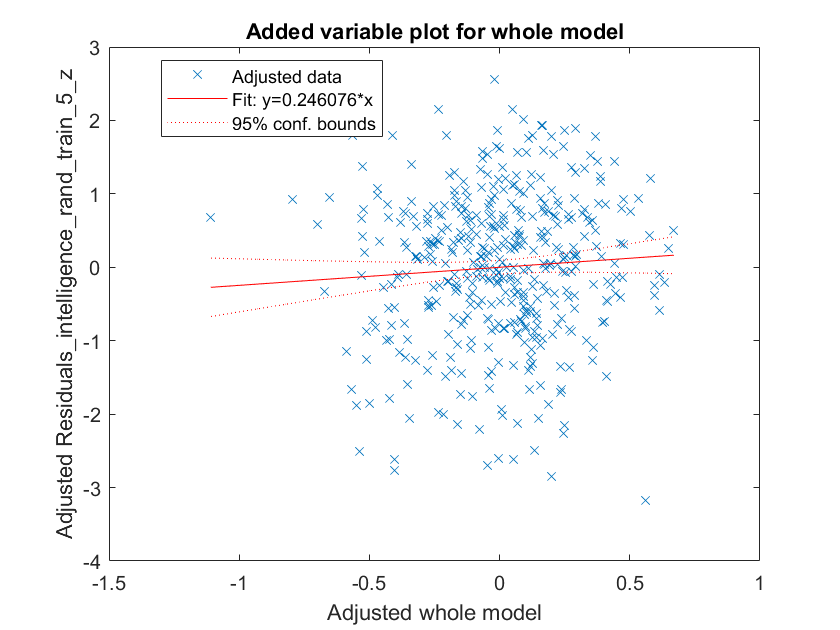

Model_Matrix = [residuals_pos_train_5_z residuals_neg_train_5_z residuals_intelligence_train_5_rand_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_pos_train_5_z', 'residuals_neg_train_5_z','Residuals_intelligence_rand_train_5_z'};

mdl_pos_neg_bcs_train_5_rand = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_5_rand);

**2. Predict the Iintelligence scores in test samples **

2.1. Test Sample 1 

Get data from replication sample 

Age_test_1 = Age_replication;
Gender_test_1 = Gender_replication;
meanFDJenk_test_1 = meanFDJenk_replication;
LQ_test_1 = LQ_replication;

Intelligence_test_1 = Intelligence_replication;

Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)


confounds = [Age_test_1 Gender_test_1 meanFDJenk_test_1 LQ_test_1];
intelligence_pred_test_1 = predict(mdl_regress_train_1_intelligence_rand,confounds);

residuals_intelligence_test_1 = (Intelligence_test_1 - intelligence_pred_test_1);
residuals_intelligence_test_1_z = normalize(residuals_intelligence_test_1,"center",c_intelligence_train_1,"scale",s_intelligence_train_1);

Retrieve NMAs

Best_case_scenario_r_values_pos = Best_case_scenario_test_samples{1,1};
Best_case_scenario_r_values_neg = Best_case_scenario_test_samples{1,2};

Take the mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Regress out the confounding variables 

confounds = [Age_test_1 Gender_test_1 meanFDJenk_test_1 LQ_test_1];


Positive_all_pred_test_1 = predict(mdl_regress_train_1_pos_bcs,confounds);

residuals_pos_test_1 = (Positive_all - Positive_all_pred_test_1);
residuals_pos_test_1_z = normalize(residuals_pos_test_1,"center",c_pos_NMA_train_1,"scale",s_pos_NMA_train_1);


Negative_all_pred_test_1 = predict(mdl_regress_train_1_neg_bcs,confounds);

residuals_neg_test_1 = (Negative_all - Negative_all_pred_test_1);
residuals_neg_test_1_z = normalize(residuals_neg_test_1,"center",c_neg_NMA_train_1,"scale",s_neg_NMA_train_1);

Xnew = [residuals_pos_test_1_z residuals_neg_test_1_z];
ypred1_rand = predict(mdl_pos_neg_bcs_train_1_rand,Xnew);

[r_model_1_rand,pval] = corr(ypred1_rand,residuals_intelligence_test_1_z);

2.2. Test Sample 2 

Get data from replication sample 

Age_test_2 = Age_replication;
Gender_test_2 = Gender_replication;
meanFDJenk_test_2 = meanFDJenk_replication;
LQ_test_2 = LQ_replication;

Intelligence_test_2 = Intelligence_replication;

Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)

confounds = [Age_test_2 Gender_test_2 meanFDJenk_test_2 LQ_test_2];
intelligence_pred_test_2 = predict(mdl_regress_train_2_intelligence_rand,confounds);

residuals_intelligence_test_2 = (Intelligence_test_2 - intelligence_pred_test_2);
residuals_intelligence_test_2_z = normalize(residuals_intelligence_test_2,"center",c_intelligence_train_2,"scale",s_intelligence_train_2);

Retrieve NMAs

Best_case_scenario_r_values_pos = Best_case_scenario_test_samples{2,1};
Best_case_scenario_r_values_neg = Best_case_scenario_test_samples{2,2};

Take the Mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Regress out the confounding variables 

confounds = [Age_test_2 Gender_test_2 meanFDJenk_test_2 LQ_test_2];

Positive_all_pred_test_2 = predict(mdl_regress_train_2_pos_bcs,confounds);

residuals_pos_test_2 = (Positive_all - Positive_all_pred_test_2);
residuals_pos_test_2_z = normalize(residuals_pos_test_2,"center",c_pos_NMA_train_2,"scale",s_pos_NMA_train_2);

Negative_all_pred_test_2 = predict(mdl_regress_train_2_neg_bcs,confounds);

residuals_neg_test_2 = (Negative_all - Negative_all_pred_test_2);
residuals_neg_test_2_z = normalize(residuals_neg_test_2,"center",c_neg_NMA_train_2,"scale",s_neg_NMA_train_2);

Xnew = [residuals_pos_test_2_z residuals_neg_test_2_z];
ypred2_rand = predict(mdl_pos_neg_bcs_train_2_rand,Xnew);

[r_model_2_rand,pval] = corr(ypred2_rand,residuals_intelligence_test_2_z);

2.3. Test Sample 3 

Get data from replication sample 

Age_test_3 = Age_replication;
Gender_test_3 = Gender_replication;
meanFDJenk_test_3 = meanFDJenk_replication;
LQ_test_3 = LQ_replication;

Intelligence_test_3 = Intelligence_replication;

Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)

confounds = [Age_test_3 Gender_test_3 meanFDJenk_test_3 LQ_test_3];
intelligence_pred_test_3 = predict(mdl_regress_train_3_intelligence_rand,confounds);

residuals_intelligence_test_3 = (Intelligence_test_3 - intelligence_pred_test_3);
residuals_intelligence_test_3_z = normalize(residuals_intelligence_test_3,"center",c_intelligence_train_3,"scale",s_intelligence_train_3);

Retrieve NMAs

Best_case_scenario_r_values_pos = Best_case_scenario_test_samples{3,1};
Best_case_scenario_r_values_neg = Best_case_scenario_test_samples{3,2};

Take the mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Regress out the confounding variables 

confounds = [Age_test_3 Gender_test_3 meanFDJenk_test_3 LQ_test_3];

Positive_all_pred_test_3 = predict(mdl_regress_train_3_pos_bcs,confounds);

residuals_pos_test_3 = (Positive_all - Positive_all_pred_test_3);
residuals_pos_test_3_z = normalize(residuals_pos_test_3,"center",c_pos_NMA_train_3,"scale",s_pos_NMA_train_3);

Negative_all_pred_test_3 = predict(mdl_regress_train_3_neg_bcs,confounds);

residuals_neg_test_3 = (Negative_all - Negative_all_pred_test_3);
residuals_neg_test_3_z = normalize(residuals_neg_test_3,"center",c_neg_NMA_train_3,"scale",s_neg_NMA_train_3);

Xnew = [residuals_pos_test_3_z residuals_neg_test_3_z];
ypred3_rand = predict(mdl_pos_neg_bcs_train_3_rand,Xnew);

[r_model_3_rand,pval] = corr(ypred3_rand,residuals_intelligence_test_3_z);

2.4. Test Sample 4 

Get data from replication sample 

Age_test_4 = Age_replication;
Gender_test_4 = Gender_replication;
meanFDJenk_test_4 = meanFDJenk_replication;
LQ_test_4 = LQ_replication;

Intelligence_test_4 = normalize(Intelligence_replication);

Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)

confounds = [Age_test_4 Gender_test_4 meanFDJenk_test_4 LQ_test_4];
intelligence_pred_test_4 = predict(mdl_regress_train_4_intelligence_rand,confounds);

residuals_intelligence_test_4 = (Intelligence_test_4 - intelligence_pred_test_4);
residuals_intelligence_test_4_z = normalize(residuals_intelligence_test_4,"center",c_intelligence_train_4,"scale",s_intelligence_train_4);

Retrieve NMAs

Best_case_scenario_r_values_pos = Best_case_scenario_test_samples{4,1};
Best_case_scenario_r_values_neg = Best_case_scenario_test_samples{4,2};

Take the mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Regress out the confounding variables 

confounds = [Age_test_4 Gender_test_4 meanFDJenk_test_4 LQ_test_4];

Positive_all_pred_test_4 = predict(mdl_regress_train_4_pos_bcs,confounds);

residuals_pos_test_4 = (Positive_all - Positive_all_pred_test_4);
residuals_pos_test_4_z = normalize(residuals_pos_test_4,"center",c_pos_NMA_train_4,"scale",s_pos_NMA_train_4);

Negative_all_pred_test_4 = predict(mdl_regress_train_4_neg_bcs,confounds);

residuals_neg_test_4 = (Negative_all - Negative_all_pred_test_4);
residuals_neg_test_4_z = normalize(residuals_neg_test_4,"center",c_neg_NMA_train_4,"scale",s_neg_NMA_train_4);

Xnew = [residuals_pos_test_4_z residuals_neg_test_4_z];
ypred4_rand = predict(mdl_pos_neg_bcs_train_4_rand,Xnew);

[r_model_4_rand,pval] = corr(ypred4_rand,residuals_intelligence_test_4_z);

2.5. Test Sample 5 

Get data from replication sample 

Age_test_5 = Age_replication;
Gender_test_5 = Gender_replication;
meanFDJenk_test_5 = meanFDJenk_replication;
LQ_test_5 = LQ_replication;

Intelligence_test_5 = Intelligence_replication;

Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)

confounds = [Age_test_5 Gender_test_5 meanFDJenk_test_5 LQ_test_5];
intelligence_pred_test_5 = predict(mdl_regress_train_5_intelligence_rand,confounds);

residuals_intelligence_test_5 = (Intelligence_test_5 - intelligence_pred_test_5);
residuals_intelligence_test_5_z = normalize(residuals_intelligence_test_5,"center",c_intelligence_train_5,"scale",s_intelligence_train_5);

Retrieve NMAs

Best_case_scenario_r_values_pos = Best_case_scenario_test_samples{5,1};
Best_case_scenario_r_values_neg = Best_case_scenario_test_samples{5,2};

Take the mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Regress out the confounding variables 

confounds = [Age_test_5 Gender_test_5 meanFDJenk_test_5 LQ_test_5];

Positive_all_pred_test_5 = predict(mdl_regress_train_5_pos_bcs,confounds);

residuals_pos_test_5 = (Positive_all - Positive_all_pred_test_5);
residuals_pos_test_5_z = normalize(residuals_pos_test_5,"center",c_pos_NMA_train_5,"scale",s_pos_NMA_train_5);

Negative_all_pred_test_5 = predict(mdl_regress_train_5_neg_bcs,confounds);

residuals_neg_test_5 = (Negative_all - Negative_all_pred_test_5);
residuals_neg_test_5_z = normalize(residuals_neg_test_5,"center",c_neg_NMA_train_5,"scale",s_neg_NMA_train_5);

Xnew = [residuals_pos_test_5_z residuals_neg_test_5_z];
ypred5_rand = predict(mdl_pos_neg_bcs_train_5_rand,Xnew);

[r_model_5_rand,pval] = corr(ypred5_rand,residuals_intelligence_test_5_z);

**3. Take the average of the performance from 5 models  **

correlations_5_rand_models = [r_model_1_rand r_model_2_rand r_model_3_rand r_model_4_rand r_model_5_rand];

z_scores_correlation_5_random_models = atanh(correlations_5_rand_models);

average_z_scores_correlation_5_random_models = mean(z_scores_correlation_5_random_models);

average_correlation_5_random_models_final = tanh(average_z_scores_correlation_5_random_models);

**4. Save rho_final & pval_final for permutation test **

Permutation_test_all_cross_val_rounds_rho{cross_validation_round,permutation_test_round} = average_correlation_5_random_models_final;

**End permutation test**

end

end

**4. Analysis Section**

all_rhos_final_correlations = cell2mat(cross_validation_100_final_correlation_HCP(:,1))

all_rhos_final_correlations = 100×1
    0.0306
    0.0458
    0.0466
    0.0451
    0.0458
    0.0402
    0.0490
    0.0426
    0.0271
    0.0428



all_rhos_final_correlations_z_scores = atanh(all_rhos_final_correlations);

mean_all_rhos_final_correlations_z_score = mean(all_rhos_final_correlations_z_scores);

mean_all_rhos_final_correlations_final = tanh(mean_all_rhos_final_correlations_z_score)

mean_all_rhos_final_correlations_final = 0.0363


Permutation_test_all_cross_val_rounds_rho_mat = cell2mat(Permutation_test_all_cross_val_rounds_rho);

find(Permutation_test_all_cross_val_rounds_rho_mat > mean_all_rhos_final_correlations_final) 

ans = 7×1
   124
   223
   275
   290
   296
   389
   794


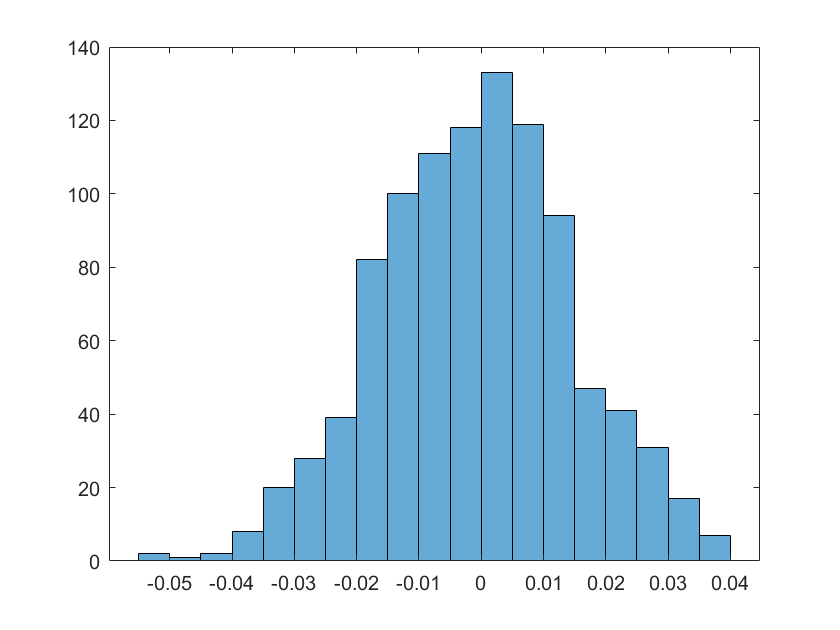

histogram(Permutation_test_all_cross_val_rounds_rho_mat)